# Создание и обработка аккорда в MATLAB

Данный скрипт использует ядро **MATLAB**, **Signal Processing Toolbox**, а также **Communications Toolbox** для добавления к сигналу шума функцией ***awgn***

### Создание синусоиды 440 Гц - ноты Ля

Задаём основную частоту колебания ***fc ***и частоту дискртизации ***fs***. Изменяя значения этих переменных можно наблюдать эффекты алиасинга при несоблюдении теоремы Котельникова.

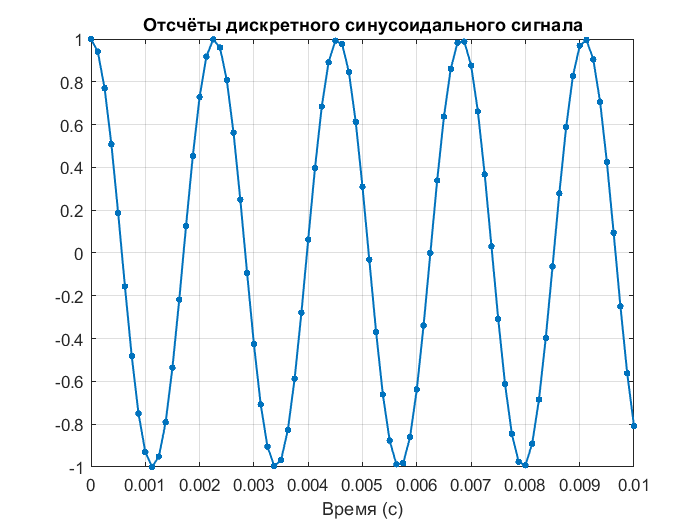

fc = 440;
fs = 8000;
dt = 1/fs;
t = 0:dt:0.5;
x = cos(2*pi*fc*t);
plot(t,x,'.-','LineWidth',1,'MarkerSize',10); 
title('Отсчёты дискретного синусоидального сигнала')
xlabel('Время (с)')
xlim([0 0.01]); grid on;

sound(x,fs)

### Генерация вектора случайных числел - шумового сигнала

Встроенные функции ***rand ***и ***randn*** позволяют получать массивы случайных числе с равномерным и нормальным распределением соответственно. Само распределение сулчайной величины можно отобразить функцией ***histogram***.

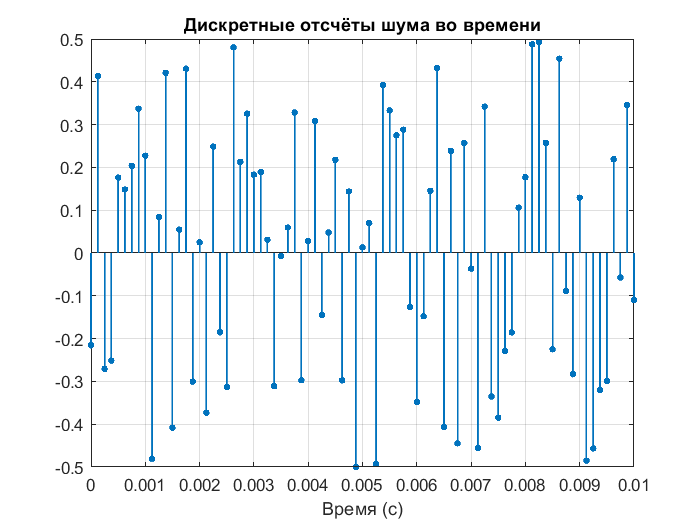

noise = rand(1,length(t));
noise = noise - 0.5;
stem(t,noise,'.-','LineWidth',1,'MarkerSize',10); 
title('Дискретные отсчёты шума во времени')
xlabel('Время (с)')
xlim([0 0.01]); grid on;

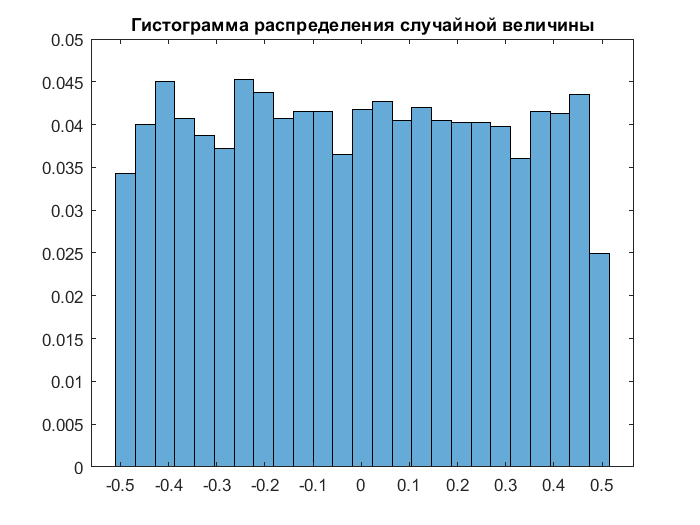

histogram(noise,25,'Normalization','probability');
title('Гистограмма распределения случайной величины')

sound(noise,fs)

### Добавление аддитивного белого гауссовского шума

Функция ***awgn ***из состава **Communications Toolbox **позволяет добавлять шум к сигналу, указывая значение отношения сигнал/шум (переменная ***snr***).

snr = 20

snr = 20

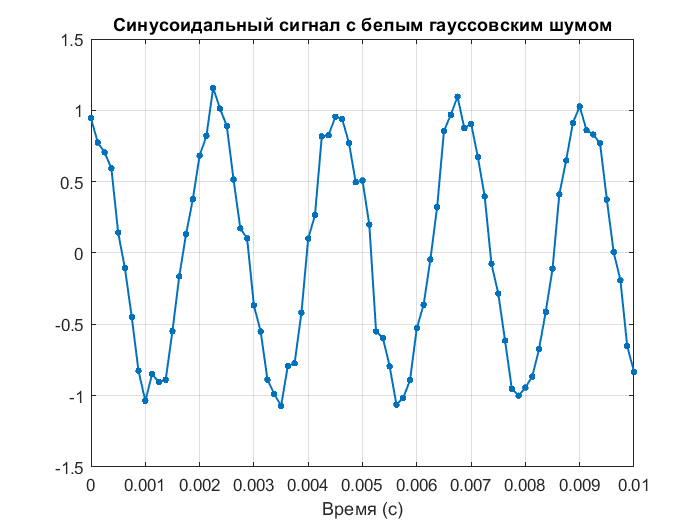

sine_noise = awgn(x,snr);
plot(t,sine_noise,'.-','LineWidth',1,'MarkerSize',10); 
title('Синусоидальный сигнал с белым гауссовским шумом')
xlabel('Время (с)')
xlim([0 0.01]); grid on;

sound(sine_noise,fs)

### Создание трёх синусоид - нот Ля, До диез и Ми

Для создания многоканального сигнала (отдельных синусоид) можно воспользоваться матричными операциями в **MATLAB**. Вектор частот ***fc*** - это столбец, в то время как вектор времени ***t*** - строка. Перемножение столбца на строку даёт в результате матрицу ***y*** из трёх строк.

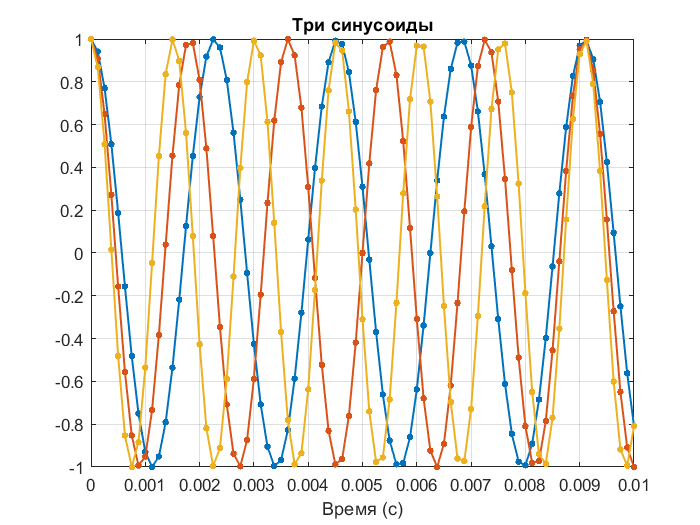

fc = [440; 550; 660];
y = cos(2*pi*fc*t);
plot(t,y,'.-','LineWidth',1,'MarkerSize',10); 
title('Три синусоиды')
xlabel('Время (с)')
xlim([0 0.01]); grid on;

sound(y(1,:),fs); pause(0.5);
sound(y(2,:),fs); pause(0.5);
sound(y(3,:),fs)

### Создание суммы синусоид (аккорда), добавление шума

Статистическая функция ***sum*** складывает элементы в столбцах матрицы. Результат - сумма трёх синусоид, которая затем нормируется в пределах [-1 1].

z = sum(y);
Achord = z/3;
snr = 10

snr = 10

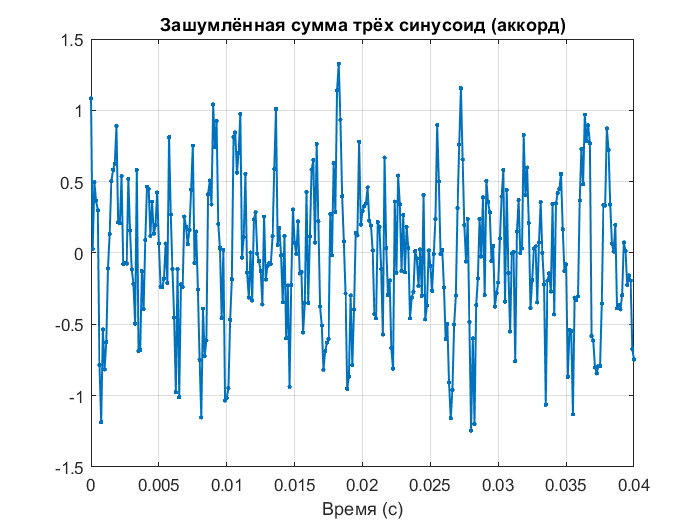

Achord = awgn(Achord,snr);
plot(t,Achord,'.-','LineWidth',1,'MarkerSize',6); 
title('Зашумлённая сумма трёх синусоид (аккорд)')
xlabel('Время (с)')
xlim([0 0.04]); grid on;

sound(Achord,fs)

### Обработка в Signal Analyzer

signalAnalyzer

### Выделение тона До диез

После открытия окна ***Signal Analyzer*** мы загружаем сигнал ***Achord*** для отображения во временной и частотной областях, указываем частоту дискретизации, делаем копию сигнала, выделяем полосно-пропускающим фильтром (band pass) частоты от 540 до 560 Гц, тем самым выбрав из смеси тон До диез, и сохраняем результат в рабочее пространство под именем ***Csharp***. 

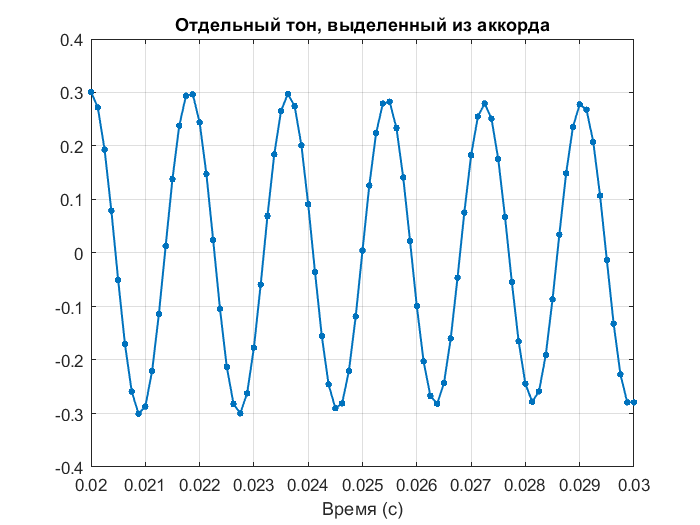

plot(t,Csharp,'.-','LineWidth',1,'MarkerSize',10); 
title('Отдельный тон, выделенный из аккорда')
xlabel('Время (с)')
xlim([0.02 0.03]); grid on;

sound(Csharp,fs)